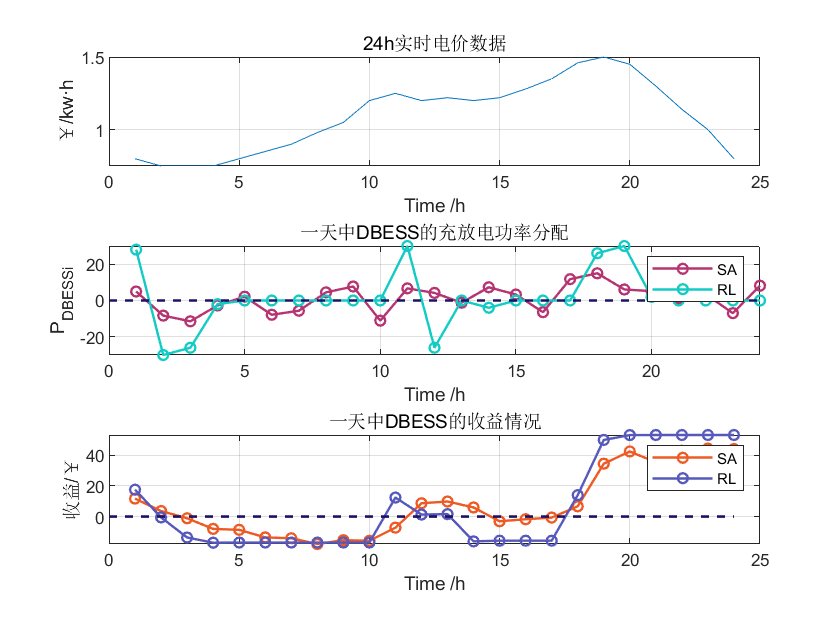

t_vis=1:24;
p=[0.8 0.75 0.75 0.75 0.8 0.85 0.9 0.98 1.05 1.2 1.25 1.2 1.22 1.2 1.22 1.28 1.35 1.46 1.5 1.45 1.3 1.14 1 0.8];
P_N=30;

figure(1)
subplot(3,1,1)
plot(t_vis,p)
grid on
xlabel('Time /h')
ylabel('￥/kw·h')
title('24h实时电价数据')

subplot(3,1,2)
plot(t_vis,P4_1(1,:),'LineWidth',1.2,'Color','#B53471','Marker',"o","MarkerSize",5);
hold on
plot(t_vis,P4_2(1,:),'LineWidth',1.2,'Color','#12CBC4','Marker',"o","MarkerSize",5);
line([0,24],[0,0],"Color",'#1B1464',"LineWidth",1.3,'LineStyle','--')
grid on
xlabel('Time /h')
ylabel('P_{DBESS}_i')
title('一天中DBESS的充放电功率分配')
axis([0,24,-P_N,P_N])
legend('SA','RL')

subplot(3,1,3)
plot(t_vis,gain4_1(1,:),'LineWidth',1.2,'Color','#EE5A24','Marker',"o","MarkerSize",5);
hold on
plot(t_vis,gain4_2(1,:),'LineWidth',1.2,'Color','#5758BB','Marker',"o","MarkerSize",5);
line([0,24],[0,0],"Color",'#1B1464',"LineWidth",1.3,'LineStyle','--')
grid on
xlabel('Time /h')
ylabel('收益/￥')
title('一天中DBESS的收益情况')
legend('SA','RL')